s = tf('s');
sys = tf(1, [1/12 0.1 -9.82/4])

sys =
 
               1
  ---------------------------
  0.08333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.




Ti = 1;
Td = 1/7;
Kp = 30;

Kpi = 1 + 1/(Ti*s);
Kpd = 1 + Td*s;
Kpid = 1 + 1/(Ti*s) + Td*s;

disp('P')

P


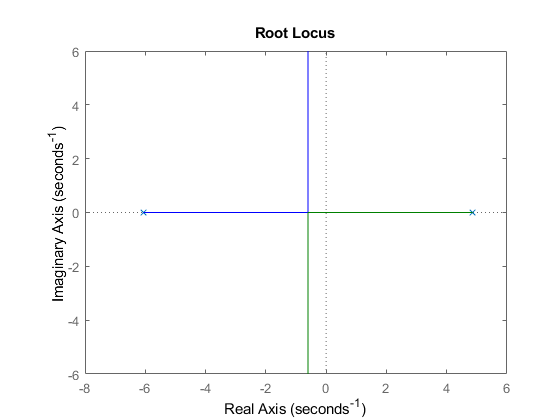

rlocus(sys)

[p,z] = pzmap(sys)

p =    -6.0608
    4.8608



z =

  0×1 empty double column vector



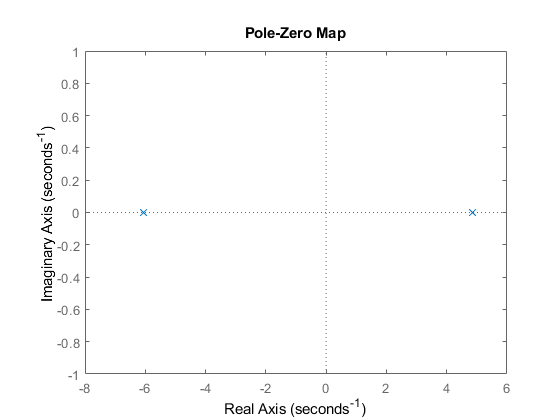

pzmap(sys)

disp('PI')

PI


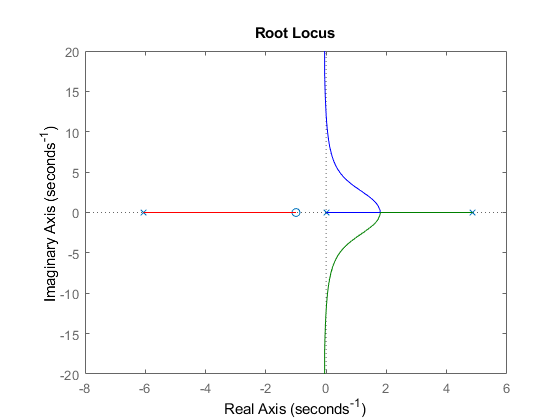

rlocus(Kpi * sys)


figure;
disp('PD')

PD


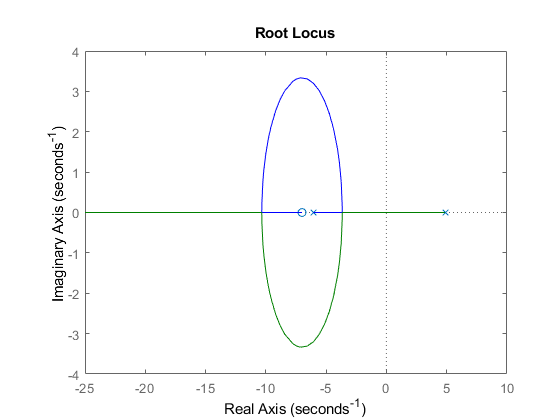

rlocus(Kpd * sys) 


K = Kp * Kpd;
G = (K * sys) / (1 + K * sys)

G =
 
         0.3571 s^3 + 2.929 s^2 - 7.521 s - 73.65
  -------------------------------------------------------
  0.006944 s^4 + 0.3738 s^3 + 2.529 s^2 - 8.012 s - 67.62
 
Continuous-time transfer function.



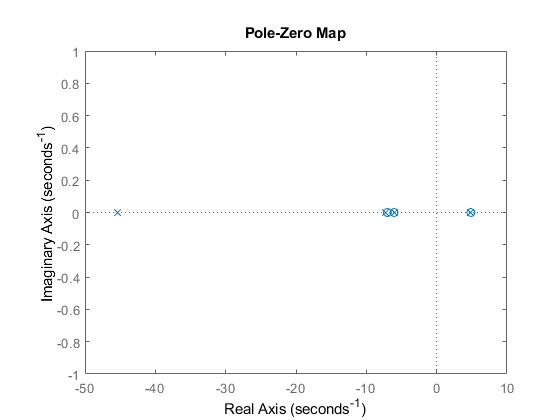

pzmap(G)

[p,z] = pzmap(G)

p =   -45.3380
    4.8608
   -7.2906
   -6.0608


z =     4.8608
   -7.0000
   -6.0608


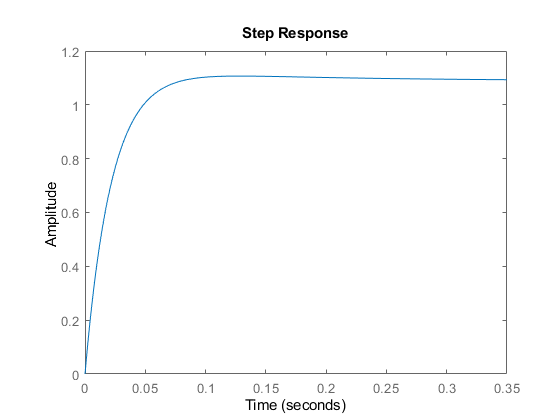

step(G)


disp('PID')

PID


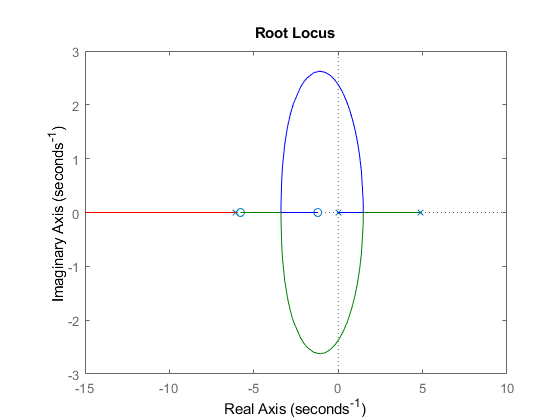

rlocus(Kpid * sys)



% display('P')
% step(Kp * sys)
% display('PI')
% step(Kpi * sys)
% display('PD')
% step(Kpd * sys)
% display('PID')
% step(Kpid * sys)

%sys2 = tf(1, [0.5 0.2 -4.91])
%rlocus(k * sys2)

%controlSystemDesigner(Kpid * sys)